# DoE Generator 

# Live Script

## Create structure listing identification parameters

clear;
clc;

F(1).Units = "[W/m/K]";
F(1).Name = "k_d";                  % Deposit thermal conductivity
F(1).Fixed = false;                 % Distributed parameter
F(1).Lo = 0;   
F(1).Hi = 0.4;
F(1).Sz = 7;
F(2).Name = "rho_d";                % deposit density
F(2).Units = "[kg/m^3]";
F(2).Fixed = false;                 % Distributed parameter
F(2).Lo = 0.5;
F(2).Hi = 100;
F(2).Sz = 10;
F(3).Name = "Ks";                   % Particle sticking probability gain
F(3).Units = "";
F(3).Fixed = true;                  % Fixed parameter
F(3).Lo = 0.001;
F(3).Hi = 0.999;
F(3).Sz = 1;                        % Size must be 1 for fixed parameter
% F(4).Name = "fRegMP";               % Friction factor regression parameters
% F(4).Units = "";
% F(4).Fixed = true;                  % Fixed parameter
% F(4).Lo = [ 0 -0.5; 0.001 -0.3; 0.1 -0.1 ];
% F(4).Hi = [ 0.25 -0.01; 0.1 -0.01; 150 0.1];
% F(4).Sz = [3,2];

## Create Sobol Sequence object and generate experiment

Sobj = SobolSequence( F, "M", 3, "K", 3 );                   % Quadratic B-spline with 3 knots for distributed parameters
% Design size is user selectable and sequence should be sccranbled scrambled.
DesignSize = 21;
Sobj = Sobj.generate( DesignSize, "Scramble", true, "Con", true );

## Generate the DoEhook object connecting the BO and ECOMO model objects

H = DoEhook();
H = H.addDesignAvailableListener( Sobj );   % Add listener for the design available event
Sobj.export();                              % Generate the parameter table

## Generate the ECOMO interface object & run the experiment. Create the Bayesian optimisation object at the end of the simulation runs.

E = ecomoInterface();
E = E.loadIdentificationData();
E = E.addRunExperimentListener( H );
H.runSimulation();

new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 
new object------ simulate from a new object !
----------------time step:  100 / 10

## Generate diagnostic plots

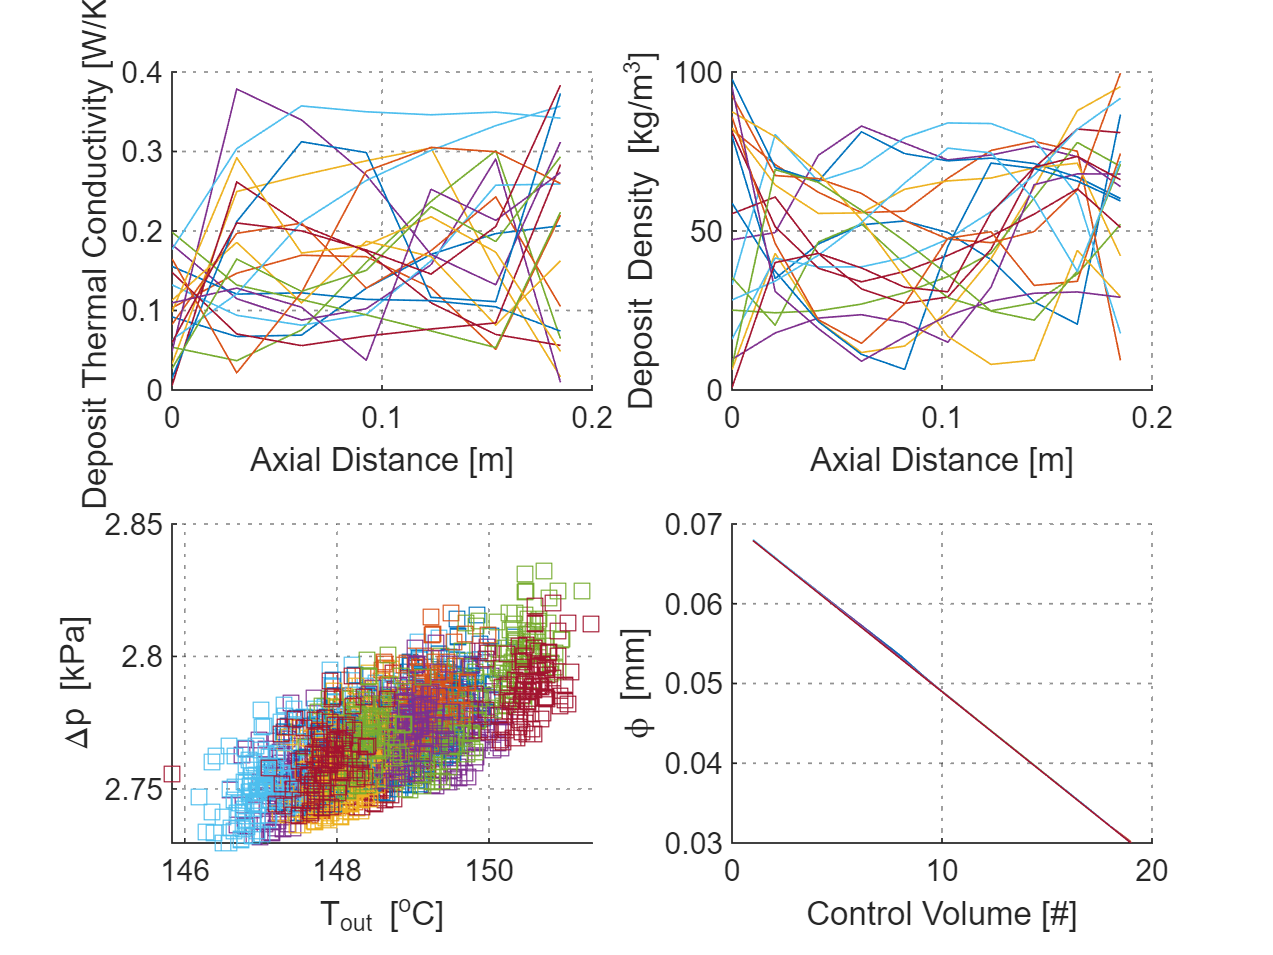

N = Sobj.NumPoints;
figure;
for Q = 1:4
    Ax( Q ) = subplot(2,2,Q);  %#ok<*SAGROW> 
    Ax( Q ).NextPlot = "add";
    grid on;
    Ax( Q ).GridAlpha = 0.5;
    Ax( Q ).GridLineStyle = ":";
end
for Q = 1:N
    plot( Ax( 1 ), E.FM(Q).ModelPara.k_d(:,1), E.FM(Q).ModelPara.k_d(:,2), '-' );     % Thermal conductivity
    plot( Ax( 2 ), E.FM(Q).ModelPara.rho_d(:,1), E.FM(Q).ModelPara.rho_d(:,2), '-');  % Deposit density
    plot( Ax( 3 ), E.FM(Q).T_out_L_degC, E.FM(Q).deltaPre_L_kPa, 's' );               % Temperature out versus delta pressure
    plot( Ax( 4 ), 1000 * E.FM( Q ).phi_soot_tn1, '-' );                              % Deposit thickness
end
xlabel( Ax( 1 ), "Axial Distance [m]");
ylabel( Ax( 1 ), "Deposit Thermal Conductivity [W/K/m]");
xlabel( Ax( 2 ), "Axial Distance [m]");
ylabel( Ax( 2 ), "Deposit Density [kg/m^3]");
xlabel( Ax( 3 ), "T_{out} [^oC]");
ylabel( Ax( 3 ), "\Deltap [kPa]")
xlabel( Ax( 4 ), "Control Volume [#]");
ylabel( Ax( 4 ), "\phi [mm]");

## Minimise the BO Acquisition Function & Update the Training Data

DataBudget = 3;
H = H.addProcessNewQueryListener( E );      % Add the necessary listener
for Q=1:DataBudget
    E = E.genNewQuery();                    % Solve the Bayesian optimisation acquisition function
    E.exportNewQuery();                     % Update the training data
end

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      20   -6.057923e-02    0.000e+00    1.376e-01
    1      40   -2.135769e+00    0.000e+00    1.184e+01    1.619e-01
    2      60   -2.274073e+00    0.000e+00    2.342e+00    4.580e-01
    3      80   -2.425819e+00    0.000e+00    3.623e-01    9.457e-01
    4     100   -3.174641e+00    0.000e+00    3.079e+00    4.786e+00
    5     120   -3.606820e+00    0.000e+00    2.741e+01    1.947e+01
    6     140   -4.481595e+00    0.000e+00    4.499e+00    2.977e+00
    7     161   -4.486857e+00    0.000e+00    3.399e+00    8.830e-01
    8     181   -4.511242e+00    0.000e+00    1.557e-01    1.070e+00
    9     201   -4.519143e+00    0.000e+00    2.251e-01    3.327e-01
   10     221   -4.568751e+00    0.000e+00    1.193e+00    1.219e+00
   11     241   -4.637572e+00    0.000e+00    1.736e+00    1.451e+00
   12     261   -4.741421e+00    0.000e+00    1

new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      20   -6.935831e-02    0.000e+00    3.336e-02
    1      40   -3.733381e-01    0.000e+00    4.990e+00    5.197e-02
    2      60   -3.863627e-01    0.000e+00    3.007e-01    1.514e-02
    3      80   -4.280951e-01    0.000e+00    4.301e-01    8.328e-01
    4     100   -4.767002e-01    0.000e+00    7.336e-01    9.342e-01
    5     120   -5.441523e-01    0.000e+00    8.366e-01    1.294e+00
    6     140   -7.045802e-01    0.000e+00    8.529e-01    3.415e+00
    7     160   -9.634188e-01    0.000e+00    2.230e+00    1.331e+01
    8     180   -9.679931e-01    0.000e+00    3.847e-01    2.031e-01
    9     200   -9.790394e-01    0.000e+00    1.163e-01    2.380e-01
   10     220   -9.966789e-01    0.000e+00    6.339e-02    3.379e-01
   11     240   -1.017085e+00    0.000e+00    5.337e-02    3.472e-01
   12     260   -1.166730e+00    0.000e+00    2

new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      20   -7.437961e-02    0.000e+00    4.318e-02
    1      40   -9.319886e-02    0.000e+00    2.404e+00    5.525e-02
    2      60   -1.033825e-01    0.000e+00    1.035e+00    3.719e-02
    3      80   -1.087811e-01    0.000e+00    9.960e-01    3.251e-02
    4     100   -1.218408e-01    0.000e+00    4.030e-01    1.930e-01
    5     120   -2.080663e-01    0.000e+00    3.985e+00    1.040e+00
    6     140   -6.383654e-01    0.000e+00    1.444e+00    4.234e+00
    7     160   -2.334546e+00    0.000e+00    1.129e+00    2.126e+01
    8     180   -3.050778e+00    0.000e+00    5.246e+00    2.571e+01
    9     200   -3.056472e+00    0.000e+00    1.074e+00    4.882e-01
   10     220   -3.077822e+00    0.000e+00    1.597e-01    5.853e-01
   11     240   -3.106038e+00    0.000e+00    1.921e-01    4.933e-01
   12     260   -3.233070e+00    0.000e+00    1

new object------ simulate from a new object !
----------------time step:  100 / 100 ---------------- 


## Plot the final "best" result from the Bayesian Optimisation Process

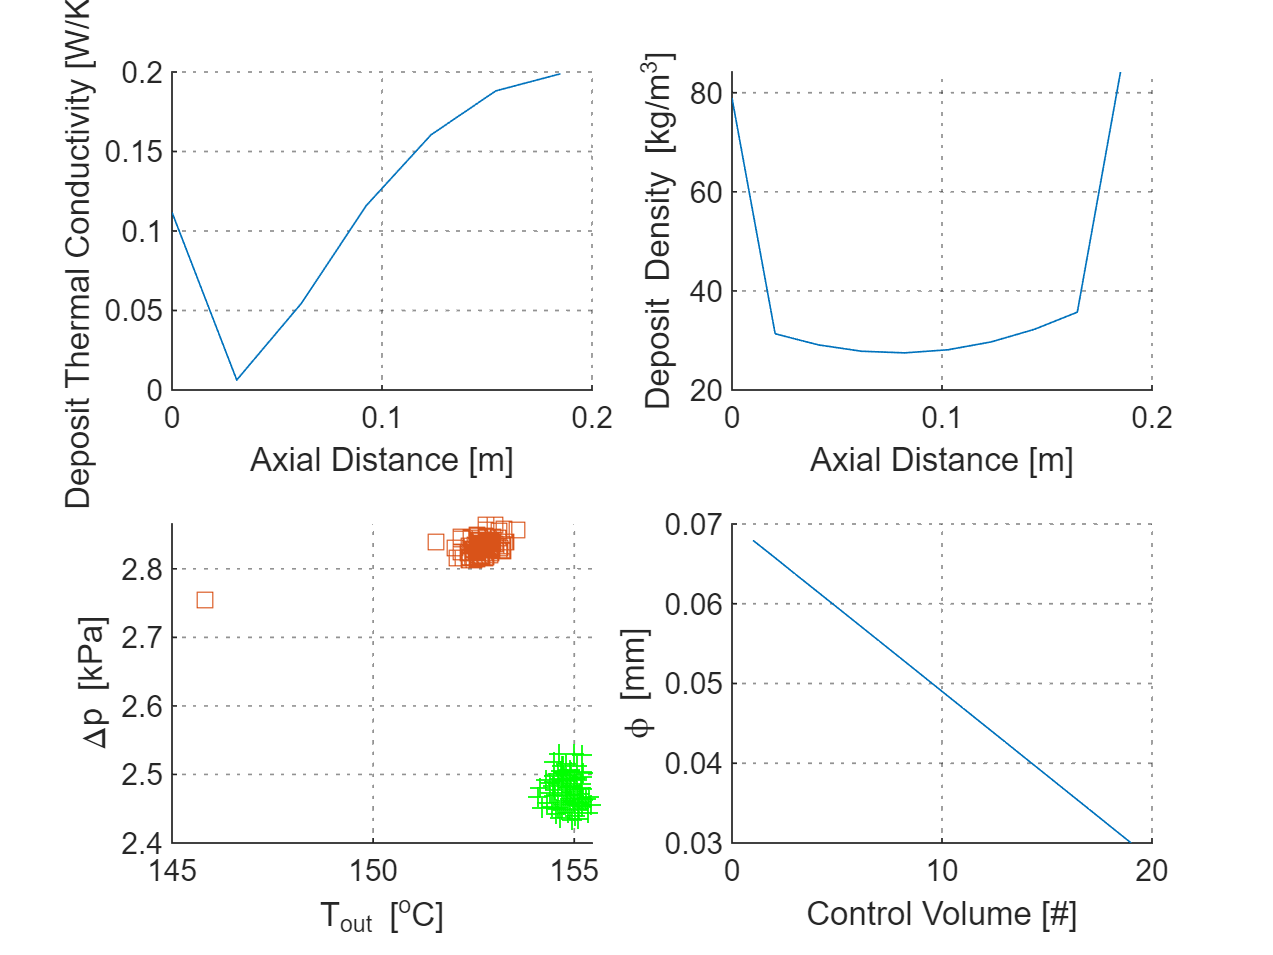

% Plot the best simulation results
E.plotBestSimulation();